# Load and Store Data

clear all;
clc;

%Set Directory 
cd('ENTER LOCATION HERE');

%Load Data Set
load('Step.mat');

%Sort Data into Variables
Command = [];
Measured = [];
Time = [];

for i = 1:length(data)

    if (data(i,2) == 100)
        Command(end+1,:) = data(i,1);
    elseif (data(i,2) == 200)
        Measured(end+1,:) = data(i,1);
    elseif (data(i,2) == 300)
        Time(end+1,:) = data(i,1);
    end

end

clear data i

## Sort Into Individual Steps and Find Average Profiles

%Find the index where step starts and ends
j = 1;

for i = 2:length(Command)

    %Starting Point
    if Command(i) ~= 0 && Command(i-1) == 0
        index(j,1) = i-1;
    end

    %Ending Point
    if Command(i) == 0 && Command(i-1) ~= 0
        index(j,2) = i;
        j = j + 1;
    end

end

clear j

%Removes first step
index(1,:) = [];

%Modify the index to Encompass Equal Time on Each Side
for i = 1:length(index)
    startTime(i) = Time(index(i,1));
    endTime(i) = Time(index(i,2));
end

startT = startTime(1) - 750;
endT = endTime(1) + 750;

j = 1;

for i = 2:length(Time)

    if Time(i) >= startT && Time(i-1) < startT
        markIdx(j,1) = i;
    end

    if Time(i) >= endT && Time(i-1) < endT
        markIdx(j,2) = i;
        j = j + 1;
    end

end

if markIdx(1,1) == 0
    markIdx(1,:) = [];
end

if markIdx(end,2) == 0
    markIdx(end,:) = [];
end

%Store Data into Steps
for i = 1:length(markIdx(:,1))

    stepCommand{i} = Command(markIdx(i,1):markIdx(i,2),1);
    stepMeasured{i} = Measured(markIdx(i,1):markIdx(i,2),1);
    stepTime{i} = Time(markIdx(i,1):markIdx(i,2),1);

end

%Find Max Data Point
for i = 1:length(stepMeasured)    
    maximum(i) = max(stepMeasured{i}(1:0.4*length(stepMeasured{i})));

    if maximum(i) > 6.2
        stepCommand{i} = [];
        stepMeasured{i} = [];
        stepTime{i} = [];
    end

end


stepCommand = stepCommand(~cellfun(@isempty,stepCommand));
stepMeasured = stepMeasured(~cellfun(@isempty,stepMeasured));
stepTime = stepTime(~cellfun(@isempty,stepTime));

% Rnew = R(~cellfun(@isempty, R))

%Shift Time Data to Start at 0
z = 1;

for i = 1:length(stepTime)
    for j = 1:length(stepTime{i})  
        if stepTime{i}(j,1) == 0
            shiftIdx(z) = j;
            z = z + 1;
        end
    end

    stepTime{i}(1:shiftIdx(i)-1,1) = stepTime{i}(1:shiftIdx(i)-1,1) - stepTime{i}(shiftIdx(i)-1,1);
    stepTime{i}(shiftIdx(i):end,1) = stepTime{i}(shiftIdx(i):end,1) + 1;

    stepTime{i} = stepTime{i} + abs(stepTime{i}(1,1));
end

%Store Step Data into one Variable
length1 = length(stepTime{1});
length2 = length1 + length(stepTime{2});
length3 = length2 + length(stepTime{3});
%length4 = length3 + length(stepTime{4});

stepData(:,1) = stepTime{1};
stepData(:,2) = stepCommand{1};
stepData(:,3) = stepMeasured{1};

stepData(length1+1:length2,1) = stepTime{2};
stepData(length1+1:length2,2) = stepCommand{2};
stepData(length1+1:length2,3) = stepMeasured{2};

stepData(length2+1:length3,1) = stepTime{3};
stepData(length2+1:length3,2) = stepCommand{3};
stepData(length2+1:length3,3) = stepMeasured{3};

% stepData(length3+1:length4,1) = stepTime{4};
% stepData(length3+1:length4,2) = stepCommand{4};
% stepData(length3+1:length4,3) = stepMeasured{4};

clear i Command index length1 length2 length3 length4 Measured stepCommand stepMeasured stepTime Time endT endTime j markIdx shiftIdx startT startTime z

%Sort Data based on Time 
[~,Idx] = sort(stepData(:,1));
sortedData = stepData(Idx,:);

%Find repeating values and average data across those
processedData = [];
pData = [];

unique_values = unique(sortedData(:,1));

for value = unique_values'

    rows_with_value = sortedData(:,1) == value;

    rows_to_average = sortedData(rows_with_value,:);

    averaged_row = mean(rows_to_average,1);
    std_deviation = std(rows_to_average,1,1);

    processedData = [processedData;averaged_row];
    pData = [pData; std_deviation];

end

%Add in Standard Deviation 
processedData(:,4) = pData(:,3);

## Calculations

%Rise Time

riseEnd = 0;

for i  = 2:length(processedData(:,3))

    if processedData(i,3) >= 0.1*max(processedData(:,2)) && processedData(i-1,3) < 0.1*max(processedData(:,2)) && i < 800
        riseStart = i;
    end

    if processedData(i,3) >= 0.9*max(processedData(:,2)) && processedData(i-1,3) < 0.9*max(processedData(:,2)) && riseEnd == 0
        riseEnd = i;
    end

    if processedData(i,2) == 0 && processedData(i-1,2) > 0
        commandEnd = i;
    end

end

riseTime = processedData(riseEnd,1) - processedData(riseStart,1);

%OverShoot
maxMeasured = max(processedData(:,3));

steadyState = mean(processedData(riseEnd:commandEnd,3));

overshoot = round(((maxMeasured - steadyState)/steadyState)*100,1);

overshootCommand = round(((steadyState-max(processedData(:,2)))/max(processedData(:,2)))*100,1);



%Plot Info
tenPercent(1,1:length(processedData(:,1))) = 0.1*max(processedData(:,2));
nintyPercent(1,1:length(processedData(:,1))) = 0.9*max(processedData(:,2));

s = ' ';
v = num2str(riseTime);
riseTimeText = strcat('Rise Time: ',s,v,' ms');

ov = num2str(overshootCommand);
overshootText = strcat('Overshoot: ',s,ov,' %');

clear averaged_row i Idx maxMeasured pData rows_to_average rows_with_value sortedData std_deviation unique_values value

## Plot Data

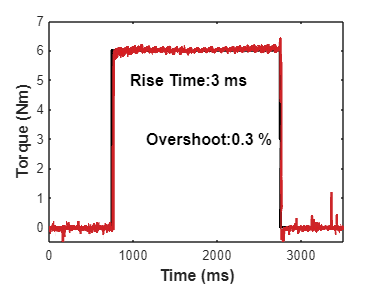

figure;
plot(processedData(:,1),processedData(:,2),'k','LineWidth',2);
hold on
plot(processedData(:,1),processedData(:,3),'Color',[204 37 41]./255,'LineWidth',2);
hold on 
x_fill = [processedData(:,1);flipud(processedData(:,1))];
y_fill = [processedData(:,3)+processedData(:,4); flipud(processedData(:,3)-processedData(:,4))];
fill(x_fill,y_fill,'r','FaceAlpha',0.3,'EdgeColor','none');
% hold on 
% plot(processedData(:,1),tenPercent,'k','LineStyle','--');
% hold on
% plot(processedData(:,1),nintyPercent,'k','LineStyle','--');
hold on 
% line([processedData(riseStart) processedData(riseStart)], [0.1*max(processedData(:,2)) 5.2],'Color','k','LineStyle','-.')
% hold on
% line([processedData(riseEnd) processedData(riseEnd)], [0.9*max(processedData(:,2)) 5.2],'Color','k','LineStyle','-.')
% hold on 
text(processedData(riseStart)+200,5,riseTimeText,'FontSize',12,'FontWeight','bold');
hold on
text(processedData(commandEnd)-1600,3,overshootText,'FontSize',12,'FontWeight','bold');
xlabel( 'Time (ms)', 'FontWeight','bold','FontSize',12);
ylabel('Torque (Nm)', 'FontWeight','bold','FontSize',12);
xlim([0 processedData(end,1)])
%legend('Perscribed','Measured','FontSize',12,'FontWeight','bold');
ylim([-0.5 7])

## Save Figure

saveas(gcf,'OpenLoop_Final','svg')